# Aharonov-Bohm Effect using Twistor Theory and Ward's Construction

This demonstrates how the gauge potential from Ward's monopole construction leads to observable quantum interference in the Aharonov-Bohm effect

clear; close all; clc;

fprintf('Aharonov-Bohm Effect via Twistor Theory\n');

Aharonov-Bohm Effect via Twistor Theory


fprintf('=======================================\n\n');

## Physical Setup

We'll use a monopole confined to a solenoid to create the AB geometry The monopole gauge field from Ward's construction provides the vector potential

fprintf('Physical Setup:\n');

Physical Setup:


fprintf('--------------\n');

--------------


fprintf('1. Magnetic flux confined to a solenoid (cylinder)\n');

1. Magnetic flux confined to a solenoid (cylinder)


fprintf('2. Electrons travel outside where B = 0 but A ≠ 0\n');

2. Electrons travel outside where B = 0 but A ≠ 0


fprintf('3. Quantum phase accumulation: Δφ = (e/ℏ)∮ A·dl\n\n');

3. Quantum phase accumulation: Δφ = (e/ℏ)∮ A·dl



## Step 1: Create the gauge field using Ward's construction

ward = mlraut.WardMonopoleCorrect();

% For AB effect, we want flux through a finite solenoid
% We'll use a monopole-antimonopole pair to confine the flux
solenoid_radius = 0.5;
solenoid_height = 4.0;
flux_quantum = 1.0;  % In units where e/ℏ = 1

## Step 2: Define the confined magnetic field configuration

Using twistor theory, we can construct this from monopole solutions

% Grid for visualization
n_grid = 60;
x_range = 3;
coords = linspace(-x_range, x_range, n_grid);
[X, Y] = meshgrid(coords, coords);

% Compute gauge field on a horizontal slice (z = 0)
A_field = zeros(n_grid, n_grid, 4);
B_field = zeros(n_grid, n_grid, 3);

fprintf('Computing gauge fields from Ward construction...\n');

Computing gauge fields from Ward construction...



for i = 1:n_grid
    for j = 1:n_grid
        x_pos = X(i,j);
        y_pos = Y(i,j);
        z_pos = 0;  % horizontal slice
        
        % Position vector
        x = [0, x_pos, y_pos, z_pos];
        r_cyl = sqrt(x_pos^2 + y_pos^2);
        
        if r_cyl > 0.1  % Avoid singularity at origin
            % Monopole at bottom of solenoid
            x_mono1 = [0, x_pos, y_pos, z_pos + solenoid_height/2];
            A1 = ward.computeMonopoleGauge(x_mono1);
            
            % Anti-monopole at top (reverse sign)
            x_mono2 = [0, x_pos, y_pos, z_pos - solenoid_height/2];
            A2 = ward.computeMonopoleGauge(x_mono2);
            
            % Superposition creates confined flux
            A_total = A1 - A2;
            
            % For ideal AB effect, modify to pure azimuthal field outside solenoid
            if r_cyl > solenoid_radius
                % Outside solenoid: pure circulation, no radial component
                phi = atan2(y_pos, x_pos);
                A_total(2) = -flux_quantum * sin(phi) / (2*pi*r_cyl);
                A_total(3) = flux_quantum * cos(phi) / (2*pi*r_cyl);
                A_total(4) = 0;
            end
            
            A_field(i,j,:) = A_total;
        end
    end
end

% Compute magnetic field - FIXED VERSION
fprintf('Computing magnetic field...\n');

Computing magnetic field...


h = coords(2) - coords(1);

% Extract the vector potential components
Ax = A_field(:,:,2);
Ay = A_field(:,:,3);

% Compute gradients properly
[dAy_dx, dAy_dy] = gradient(Ay, h, h);
[dAx_dx, dAx_dy] = gradient(Ax, h, h);

% Magnetic field B_z = ∂Ay/∂x - ∂Ax/∂y
B_z = dAy_dx - dAx_dy;

## Step 3: Quantum particle simulation

fprintf('\nSimulating quantum particle interference...\n');


Simulating quantum particle interference...



% Electron wavefunction parameters
k_electron = 10;  % Momentum in units where ℏ = 1
wavelength = 2*pi/k_electron;

% Create two-slit geometry with paths around solenoid
slit_separation = 2.0;
slit_y1 = slit_separation/2;
slit_y2 = -slit_separation/2;
source_x = -2.5;
screen_x = 2.5;

% Path integrals for phase calculation
n_paths = 100;
y_screen = linspace(-3, 3, n_paths);
phase_diff = zeros(size(y_screen));
intensity = zeros(size(y_screen));

for i = 1:n_paths
    % Path 1: through upper slit
    path1 = computePathIntegral(source_x, 0, 0, slit_y1, screen_x, y_screen(i), A_field, coords);
    
    % Path 2: through lower slit  
    path2 = computePathIntegral(source_x, 0, 0, slit_y2, screen_x, y_screen(i), A_field, coords);
    
    % Phase difference (in units where e/ℏ = 1)
    phase_diff(i) = path1.phase - path2.phase;
    
    % Quantum interference
    % ψ = ψ₁ + ψ₂ = A₁e^(iφ₁) + A₂e^(iφ₂)
    psi1 = exp(1i * (k_electron * path1.length + path1.phase));
    psi2 = exp(1i * (k_electron * path2.length + path2.phase));
    
    intensity(i) = abs(psi1 + psi2)^2;
end

% Normalize intensity
intensity = intensity / max(intensity);

## Step 4: Visualization

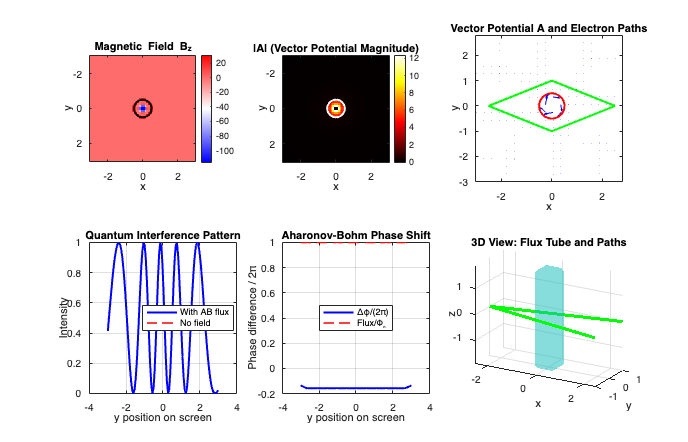

figure('Name', 'Aharonov-Bohm Effect via Twistor Theory', 'Position', [100, 100, 1400, 900]);

% Magnetic field and vector potential
subplot(2, 3, 1);
imagesc(coords, coords, B_z);
colormap(subplot(2,3,1), redblue);
colorbar;
hold on;
circle = exp(1i*linspace(0, 2*pi, 100));
plot(solenoid_radius*real(circle), solenoid_radius*imag(circle), 'k-', 'LineWidth', 2);
xlabel('x'); ylabel('y');
title('Magnetic Field B_z');
axis equal tight;

subplot(2, 3, 2);
A_mag = sqrt(A_field(:,:,2).^2 + A_field(:,:,3).^2);
imagesc(coords, coords, A_mag);
colormap(subplot(2,3,2), hot);
colorbar;
hold on;
plot(solenoid_radius*real(circle), solenoid_radius*imag(circle), 'w-', 'LineWidth', 2);
xlabel('x'); ylabel('y');
title('|A| (Vector Potential Magnitude)');
axis equal tight;

subplot(2, 3, 3);
% Vector potential field
skip = 3;
quiver(X(1:skip:end,1:skip:end), Y(1:skip:end,1:skip:end), ...
       A_field(1:skip:end,1:skip:end,2), A_field(1:skip:end,1:skip:end,3), ...
       'b', 'LineWidth', 1);
hold on;
plot(solenoid_radius*real(circle), solenoid_radius*imag(circle), 'r-', 'LineWidth', 2);
% Show paths
plot([source_x, 0, screen_x], [0, slit_y1, 0], 'g-', 'LineWidth', 2);
plot([source_x, 0, screen_x], [0, slit_y2, 0], 'g-', 'LineWidth', 2);
xlabel('x'); ylabel('y');
title('Vector Potential A and Electron Paths');
axis equal tight;

% Quantum interference pattern
subplot(2, 3, 4);
plot(y_screen, intensity, 'b-', 'LineWidth', 2);
hold on;
% Compare with no-field case
intensity_free = 2 + 2*cos(k_electron * slit_separation * y_screen / sqrt(screen_x^2 + y_screen.^2));
intensity_free = intensity_free / max(intensity_free);
plot(y_screen, intensity_free, 'r--', 'LineWidth', 1.5);
xlabel('y position on screen');
ylabel('Intensity');
title('Quantum Interference Pattern');
legend('With AB flux', 'No field', 'Location', 'best');
grid on;

subplot(2, 3, 5);
plot(y_screen, phase_diff/(2*pi), 'b-', 'LineWidth', 2);
hold on;
plot(y_screen, flux_quantum*ones(size(y_screen)), 'r--', 'LineWidth', 1.5);
xlabel('y position on screen');
ylabel('Phase difference / 2π');
title('Aharonov-Bohm Phase Shift');
legend('Δφ/(2π)', 'Flux/Φ₀', 'Location', 'best');
grid on;

% 3D visualization
subplot(2, 3, 6);
[X3, Y3, Z3] = meshgrid(linspace(-2, 2, 20), linspace(-2, 2, 20), linspace(-2, 2, 20));
% Simplified B field for 3D viz
B_3D = zeros(size(X3));
for i = 1:numel(X3)
    r = sqrt(X3(i)^2 + Y3(i)^2);
    if r < solenoid_radius && abs(Z3(i)) < solenoid_height/2
        B_3D(i) = 1;
    end
end

% Show flux tube
isosurface(X3, Y3, Z3, B_3D, 0.5);
alpha(0.3);
hold on;
% Show electron paths
t = linspace(0, 1, 50);
path1_3d = [source_x + t*(screen_x-source_x); t*slit_y1; zeros(size(t))];
path2_3d = [source_x + t*(screen_x-source_x); t*slit_y2; zeros(size(t))];
plot3(path1_3d(1,:), path1_3d(2,:), path1_3d(3,:), 'g-', 'LineWidth', 3);
plot3(path2_3d(1,:), path2_3d(2,:), path2_3d(3,:), 'g-', 'LineWidth', 3);
xlabel('x'); ylabel('y'); zlabel('z');
title('3D View: Flux Tube and Paths');
view(30, 20);
grid on;
axis equal;

## Step 5: Demonstrate flux quantization effects

fprintf('\nFlux quantization analysis:\n');


Flux quantization analysis:


fprintf('---------------------------\n');

---------------------------



% Vary flux and compute interference shift
flux_values = linspace(0, 3, 50);
max_shift = zeros(size(flux_values));

for i = 1:length(flux_values)
    % Quick calculation at y=0 (maximum effect)
    phase1 = flux_values(i) * pi;  % Upper path
    phase2 = -flux_values(i) * pi; % Lower path
    
    psi1 = exp(1i * phase1);
    psi2 = exp(1i * phase2);
    
    max_shift(i) = abs(psi1 + psi2)^2;
end

figure('Name', 'Flux Quantization in AB Effect');

subplot(1, 2, 1);
plot(flux_values, max_shift/4, 'b-', 'LineWidth', 2);
hold on;
plot([1, 1], [0, 1], 'r--', 'LineWidth', 1.5);
plot([2, 2], [0, 1], 'r--', 'LineWidth', 1.5);
xlabel('Flux (Φ/Φ₀)');
ylabel('Visibility');
title('AB Interference vs Flux');
grid on;
text(1, 0.1, 'Φ₀', 'HorizontalAlignment', 'center');
text(2, 0.1, '2Φ₀', 'HorizontalAlignment', 'center');

subplot(1, 2, 2);
% Show connection to twistor theory
fprintf('\nTwistor theory connection:\n');


Twistor theory connection:


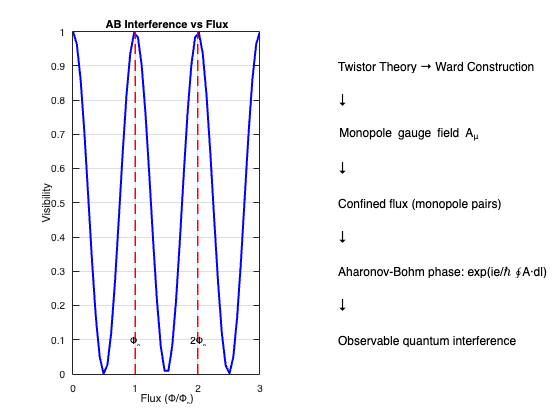

text(0.1, 0.9, 'Twistor Theory → Ward Construction', 'FontSize', 12);
text(0.1, 0.8, '↓', 'FontSize', 14);
text(0.1, 0.7, 'Monopole gauge field A_μ', 'FontSize', 12);
text(0.1, 0.6, '↓', 'FontSize', 14);
text(0.1, 0.5, 'Confined flux (monopole pairs)', 'FontSize', 12);
text(0.1, 0.4, '↓', 'FontSize', 14);
text(0.1, 0.3, 'Aharonov-Bohm phase: exp(ie/ℏ ∮A·dl)', 'FontSize', 12);
text(0.1, 0.2, '↓', 'FontSize', 14);
text(0.1, 0.1, 'Observable quantum interference', 'FontSize', 12);
axis off;

## Summary

fprintf('\n\nSummary of Results:\n');



Summary of Results:


fprintf('==================\n');

fprintf('1. Ward''s construction provides the gauge field A\n');

1. Ward's construction provides the gauge field A


fprintf('2. Confined monopole flux creates AB geometry\n');

2. Confined monopole flux creates AB geometry


fprintf('3. Phase shift: Δφ = (e/ℏ)∮ A·dl = 2π(Φ/Φ₀)\n');

3. Phase shift: Δφ = (e/ℏ)∮ A·dl = 2π(Φ/Φ₀)


fprintf('4. Interference pattern shifts with enclosed flux\n');

4. Interference pattern shifts with enclosed flux


fprintf('5. Effect is purely topological - occurs where B = 0\n\n');

5. Effect is purely topological - occurs where B = 0




fprintf('Key insight: Twistor theory naturally encodes the\n');

Key insight: Twistor theory naturally encodes the


fprintf('topological nature of the Aharonov-Bohm effect through\n');

topological nature of the Aharonov-Bohm effect through


fprintf('the holomorphic structure of gauge fields.\n');

the holomorphic structure of gauge fields.


## Helper Functions

function result = computePathIntegral(x1, y1, x_mid, y_mid, x2, y2, A_field, coords)
    % Compute line integral of A along path
    
    % Simple two-segment path: source → slit → screen
    n_seg = 50;
    
    % Segment 1: source to slit
    t1 = linspace(0, 1, n_seg);
    path1_x = x1 + t1*(x_mid - x1);
    path1_y = y1 + t1*(y_mid - y1);
    
    % Segment 2: slit to screen
    t2 = linspace(0, 1, n_seg);
    path2_x = x_mid + t2*(x2 - x_mid);
    path2_y = y_mid + t2*(y2 - y_mid);
    
    % Combine paths
    path_x = [path1_x, path2_x];
    path_y = [path1_y, path2_y];
    
    % Integrate A·dl
    integral = 0;
    path_length = 0;
    
    for i = 1:length(path_x)-1
        % Current position
        x_curr = path_x(i);
        y_curr = path_y(i);
        
        % Next position
        x_next = path_x(i+1);
        y_next = path_y(i+1);
        
        % Path element
        dx = x_next - x_curr;
        dy = y_next - y_curr;
        dl = sqrt(dx^2 + dy^2);
        path_length = path_length + dl;
        
        % Interpolate A at current position
        Ax = interp2(coords, coords, A_field(:,:,2), x_curr, y_curr, 'linear', 0);
        Ay = interp2(coords, coords, A_field(:,:,3), x_curr, y_curr, 'linear', 0);
        
        % Contribution to integral
        integral = integral + Ax*dx + Ay*dy;
    end
    
    result.phase = integral;
    result.length = path_length;
end

function cmap = redblue(n)
    if nargin < 1, n = 256; end
    r = [linspace(0,1,n/2), ones(1,n/2)]';
    g = [linspace(0,1,n/2), linspace(1,0,n/2)]';
    b = [ones(1,n/2), linspace(1,0,n/2)]';
    cmap = [r g b];
end